# AEM 7500: Resource Economics

## Problem Set 1, due **October 1, 2026**

### **Josephine Freis**

### **I. Deterministic Dynamic Programming**

#### **1. a) Dynamic optimization problem**

$v(K_0) = \max_{\{c_t | c_t \in C(K_t)\}_{t=0}^{\infty}} \sum_{t=0}^{\infty} \beta ^t \ln{c_t}$  where $C(K_t)$ is the set of feasible consumption levels given $K_t$ ,

s.t.    $K_{t+1} - K_t = aK_t - \frac{bK_t^2}{2} - c_t$

         $c_t, K_t \geq 0$  $\forall t = 0, 1, 2, ...$ , and

          $K_0$ given,

where $\beta = \frac{1}{1+\rho}$  henceforth.

#### b) Bellman equation


$$v(K_t) = \max_{c_t \in C(K_t)} \ln{c_t} + \beta v(K_{t+1})$$


s.t.    $K_{t+1} - K_t = aK_t - \frac{bK_t^2}{2} - c_t$

         $c_t, K_{t+1} \geq 0$ .

#### c) Interpretation

The value function is $v(K_t)$ which represents the present discounted value from now on of the stream of per-period payoffs when consumption is chosen optimally, given the current state of farm capital $K_t$.

The continuation value is $v(K_{t+1})$ which represents the value of all future payoffs starting from the next period when consumption is chosen optimally given next period's capital stock, which involves a tradeoff with today's choice of consumption.

#### d) Redefine control variable


$$v(K_t) = \max_{K_{t+1}} \ln {(aK_t - \frac{bK_t^2}{2} - K_{t+1} + K_t})+ \beta v(K_{t+1})$$


s.t. $0 \leq K_{t+1} < aK_t - \frac{bK_t^2}{2} + K_t$ .

#### e) Solve for value, policy function

In PS1_Q1.m I solve for the value function and policy function as functions of capital stock K. In lines 20-23, I set parameter values as given in the problem. In lines 26-30, I set up the discretized K arrays. In lines 33-35, I define f_k as production plus existing capital, which is the total resources available. Subtracting K′ gives consumption, and taking the log gives the payoff matrix. I then initialize values for the loop in lines 38-40. The while loop in lines 43 to 55 calculates for each K, K' pair the value function, finds the arg max, and continues looping until the value function converges as defined by our "diff" condition. The arg max (K' that maximizes value for each K) is identified as "kprime_pol", the policy function.

% Setup
clearvars;
close all;
clc;

% Define variables and parameters
rho = 0.05;
beta = 1 / (1 + rho);
a = 48.05;
b = 3;

% Create k grids
num_k = 30;
num_kprime = 30;

k = (1:num_k)';
kprime = 1:num_kprime;

% Describe laws of problem
f_k = a*k - b*k.^2 / 2 + k;
c = f_k - kprime; % consumption for every pair
pii = log(c); % payoffs

% Initialize for loop
v = zeros(num_k, 1);
ep = 1e-6;
diff = 1;

% Solve
while diff > ep
    % Reset v to be the previous version
    v_old = v;

    % value of v
    vv = pii + beta * v';

    % For each k, choose kprime to maximize vv
    [v, kprime_pol] = max(vv, [], 2);

    % Calculate diff
    diff = max(abs(v - v_old));
end

% Print results in table
results1 = table(k, v, kprime_pol, 'VariableNames', {'State', 'Value', 'Policy'})

results1 = 30×3 table
    State    Value     Policy
    _____    ______    ______

      1      122.55      13  
      2      123.39      15  
      3      123.82      15  
      4      124.11      15  
      5      124.31      16  
      6      124.47      16  
      7      124.59      16  
      8      124.69      16  
      9      124.77      16  
     10      124.84      16  
     11      124.89      16  
     12      124.93      16  
     13      124.96      16  
     14      124.99      16  
     15         125      16  
     16      125.01      16  

	Get insights using Copilot


#### f) Plot optimal trajectories

Next I solve for the optimal trajectories of capital K(t) and consumption C(t) starting from K₀ = 5. In lines 63-67, I set the number of periods T and initialize the capital path with K₀ = 5. In lines 70-72, I use the policy function to fill in the rest of the capital path: for each period, next period's capital is the policy function evaluated at the current capital. In line 75, I compute consumption in each period from the law of motion, as production plus current capital minus next period's capital. In lines 78-88, I plot both paths against time.

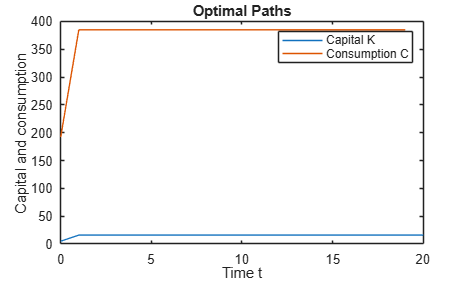

% Pick number of periods
T = 20;

% Store capital in vector
k_path = zeros(T + 1, 1);
k_path(1) = 5; % start at k0 = 5

% Simulate the optimal capital path
for t = 1:T
    k_path(t + 1) = kprime_pol(k_path(t));
end

% Consumption from law of motion
c_path = f_k(k_path(1:T)) - k_path(2:T + 1);

% Plot optimal paths
t_k = 0:T;
t_c = 0:T-1;

figure
plot(t_k, k_path)
hold on
plot(t_c, c_path)
legend('Capital K', 'Consumption C')
xlabel('Time t')
title('Optimal Paths')
ylabel('Capital and consumption')

#### g) Interpret results

The value function v(K) rises with capital up to K = 16 and then falls slightly. The policy function shows that for most starting values of K, the optimal next-period capital is K′ = 16, so 16 is the steady state. Starting from K₀ = 5, capital rises to 16 in only one period and stays there. This one-period jump is partially due to the coarse grid for K (integers 1-30 only). Consumption starts near 190 units and rises to about 385 which is the steady-state output, F(16). We can see that the farming family gives up some consumption early to build capital, which raises consumption in every later period.

#### 2. a) Bellman equation, finite horizon problem

$v_t(K_t) = \max_{K_{t+1}} \ln {(aK_t - \frac{bK_t^2}{2} - K_{t+1} + K_t})+ \beta v_{t+1}(K_{t+1})$ for $t= 0, 1,2,3$, and


$$v_T(K_T) = \ln (aK_T - \frac{bK_T^2}{2} + K_T)$$


s.t. $0 \leq K_{t+1} < aK_t - \frac{bK_t^2}{2} + K_t$ $\forall t = 0, 1, 2, 3$, and

$0 < aK_T - \frac{bK_T^2}{2} + K_T$ , i.e., $c_T > 0$ .

#### b) Interpretation

The value function is $v_t(K_t)$ which represents the present discounted value from now through the last period of the stream of per-period payoffs when next period's capital is chosen optimally, given the current state of farm capital $K_t$.

The continuation value is $v_t(K_{t+1})$ which represents the value of all future payoffs starting from the next period through the final period, when future capital choices are made optimally given next period's capital stock, which involves a tradeoff with today's choice of consumption. Note that there is no continuation value in the Bellman for $t = T =4$, as there is no "future" after the last period.

#### c) Solve

In PS1_Q2.m, I solve for the value function and policy function as functions of capital stock K and time t, for the finite horizon problem with T = 4. In lines 19-29, I set parameter values and the discretized K grid, as before. In lines 32-34, I compute f_k, consumption, and the payoff matrix, the same way as in the infinite horizon case. In lines 39-42, I initialize the value function and set the value function in the last period, t = T, as the payoff from consuming all available resources, since there is no continuation value. In lines 45-54, I iterate backwards from t = T−1 to t = 0: in each period, I compute the value of each K, K′ pair as today's payoff plus the discounted value next period, take the arg max across K′ for each K, and store the results in the corresponding column of v_t and kprime_t. The result is a full time path of value and policy functions, one column for each period from t = 0 to t = T.

% Setup
clearvars;
clc;

% Define variables and parameters
rho = 0.05;
beta = 1 / (1 + rho);
a = 48.05;
b = 3;

% Create k grids
num_k = 30;
num_kprime = 30;

k = (1:num_k)';
kprime = 1:num_kprime;

% Describe laws of problem
f_k = a*k - b*k.^2 / 2 + k;
c = f_k - kprime; % consumption for every pair
pii = log(c); % payoffs

T = 4;

% Initialize value function
v = zeros(num_k, T + 1);

% Value function at t=T
v_t(:, T+1) = log(a*k - b*k.^2/2 + k);

% Solve using backwards iteration
for t = T-1:-1:0
    % Initialize vv
    vv = pii + beta * v_t(:, t+2)';

    % Choose optimal actions
    [v_now, kprime_now] = max(vv, [], 2);
    v_t(:, t + 1) = v_now;
    kprime_t(:, t+1) = kprime_now;

end

% Print results in table
results2 = array2table([k, v_t, kprime_t], 'VariableNames', ...
    {'K','v_t0','v_t1','v_t2','v_t3','v_t4','K_t0','K_t1','K_t2','K_t3'})

results2 = 30×10 table
    K      v_t0      v_t1      v_t2      v_t3      v_t4     K_t0    K_t1    K_t2    K_t3
    __    ______    ______    ______    ______    ______    ____    ____    ____    ____

     1    24.642    19.746    14.606    9.2101    3.8618     13      13      13      13 
     2     25.48    20.585    15.444    10.047    4.5229     15      15      15      15 
     3    25.911    21.016    15.875    10.478    4.8952     15      15      15      15 
     4    26.193    21.297    16.157    10.759    5.1487     15      15      15      15 
     5    26.398    21.502    16.362    10.964    5.3363     16      16      16      16 
     6    26.

#### d) Plot optimal trajectories

Next I solve for the optimal trajectories of capital K(t) and consumption C(t) starting from K₀ = 5, over the family's finite horizon until T = 4. In lines 67-70, I use the time-specific policy function to fill in the rest of the capital path: for each period t, next period's capital is the policy function evaluated at the current capital and the current period. I then set capital at t = T+1 to 0 since the family's lifetime ends at T. In line 73, I compute consumption in each period from the law of motion, the same as in the infinite horizon case. In lines 76-86, I plot both paths against time.

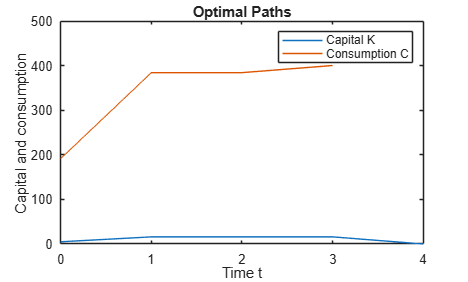

% Store capital in vector
k_path = zeros(T + 1, 1);
k_path(1) = 5; % start at k0 = 5

% Simulate the optimal capital path
for t = 0:T-1
    k_path(t + 2) = kprime_t(k_path(t+1), t+1);
end
k_path(T+1) = 0;

% Consumption from law of motion
c_path = f_k(k_path(1:T)) - k_path(2:T + 1);

% Plot optimal paths
t_k = 0:T;
t_c = 0:T-1;

figure
plot(t_k, k_path)
hold on
plot(t_c, c_path)
legend('Capital K', 'Consumption C')
xlabel('Time t')
title('Optimal Paths')
ylabel('Capital and consumption')

#### e) Interpret results

Starting from K₀ = 5, capital rises to 16 by t = 1, similar to the infinite horizon case, and stays there through t = 3. In the last period, capital drops to 0, since any capital left at the end of the family's lifetime produces no further value. Consumption starts near 192 units, rises to about 385 once capital reaches its interior peak of 16, and then jumps to about 401 in the last period, as the family consumes both its usual output and the capital it would otherwise leave behind. This is the key difference from the infinite horizon case: because the family knows exactly when its lifetime ends, it draws down its capital stock entirely rather than maintaining it forever. Thus there is a consumption spike at t = 3, differently than in the infinite horizon path.

### **I. Stochastic Dynamic Programming**

#### **3. a)** Infinite problem, Bellman equation


$$v(K_t) = \max_{c_t \in C(K_t)} \ln{c_t} + \beta \, \mathbb{E} ( v(K_{t+1}) | K_t, c_t)$$


s.t.    $K_{t+1} - K_t = aK_t - \frac{bK_t^2}{2} - c_t + \varepsilon_t$

         $c_t, K_{t+1} \geq 0$ .

#### b) Interpretation

The value function is $v(K_t)$ which represents the present discounted value from now on of the stream of per-period payoffs when consumption is chosen optimally, given the current state of farm capital $K_t$.

The continuation value is $\mathbb{E}(v(K_{t+1}))$ which represents the expected value of all future payoffs starting from the next period when consumption is chosen optimally given next period's capital stock, which is not known with certainty due to the random shock, and which involves a tradeoff with today's choice of consumption.

#### c) Redefine control variable

Let $I \equiv F(K) - C + K$, so now $K_{t+1} = I_t + \varepsilon_t$ . Then


$$v(K_t) = \max_{I} \ln {(aK_t - \frac{bK_t^2}{2} - I + K_t})+ \beta \, \mathbb{E} v(I+\varepsilon_t)$$


s.t. $2 \leq I \leq 29$ and 

$aK_t - \frac{bK_t^2}{2} + K_t >I$.

#### d) Solve for value, policy function

In PS1_Q3.m, I solve for the value function and policy function as functions of capital stock K, for the stochastic infinite horizon problem with control variable I. In lines 19-26, I set parameter values as given in the problem, including the shock distribution. In lines 29-33, I set up the discretized K and I grids, where I ranges from 2 to 29 to ensure K′ = I + ε stays on the grid regardless of the realized shock (as in c)). In line 36, I define f_k as production plus existing capital; subtracting I gives consumption, and taking the log gives the payoff matrix. I then initialize values for the loop in lines 41-43. The while loop in lines 46-59 calculates, for each I, the expected continuation value by averaging the value function over the three possible realizations of K′ = I + ε, weighted by their probabilities. I then add this expected continuation value to the payoff matrix, find the arg max across I for each K, and continue looping until the value function converges as defined by our "diff" condition. The arg max (I that maximizes value for each K) is identified as "I_pol", the policy function, since it determines the distribution of next period's capital. In line 62, I convert this from a grid index into the investment level it corresponds to, since the I grid starts at 2 rather than 1, and it is this converted policy, "I_star", that the table reports.

% Setup
clearvars;
clc;

% Define variables and parameters
rho = 0.05;
beta = 1 / (1 + rho);
a = 48.05;
b = 2;

% Define shock distribution
eps_vals = [-1, 0, 1];
eps_probs = [0.25, 0.45, 0.30];

% Create I grid
Igrid = 2:29;

% Create k
num_k = 30;
k = (1:num_k)';

% Describe laws of problem
f_k = a*k - b*k.^2 / 2 + k;
c = f_k - Igrid; % consumption for every pair
pii = log(c); % payoffs

% Initialize for loop
v = zeros(num_k, 1);
ep = 1e-6;
diff = 1;

% Solve
while diff > ep
    % Reset v to be the previous version
    v_old = v;

    % value of v
    Ev = 0.25*v(Igrid-1) + 0.45*v(Igrid) + 0.30*v(Igrid + 1);
    vv = pii + beta * Ev';

    % For each k, choose kprime to maximize vv
    [v, I_pol] = max(vv, [], 2);

    % Calculate diff
    diff = max(abs(v - v_old));
end

% Convert policy index to investment level
I_star = reshape(Igrid(I_pol), [], 1);

% Print results in table
results3 = table(k, v, I_star, 'VariableNames', {'State', 'Value', 'Policy'})

results3 = 30×3 table
    State    Value     Policy
    _____    ______    ______

      1      130.49      16  
      2      131.42      20  
      3      131.89      22  
      4       132.2      23  
      5      132.43      23  
      6       132.6      23  
      7      132.75      23  
      8      132.86      23  
      9      132.96      24  
     10      133.05      24  
     11      133.12      24  
     12      133.19      24  
     13      133.24      24  
     14      133.29      24  
     15      133.33      24  
     16      133.37      24  

	Get insights using Copilot


#### e) Plot optimal trajectories

Next I simulate and plot the optimal trajectories of capital K(t), investment I(t), and consumption C(t) for the stochastic problem, starting from K₀ = 5. In lines 70-71, I set the number of periods T and the number of simulated paths, and in line 74 I set a random seed so the simulated paths are reproducible. In lines 77-83, I draw the shock realizations: for each of the five simulations I take T independent draws from the three-point distribution of ε weighted by the probabilities given in the problem. In lines 86-89, I initialize the capital and investment paths and set initial capital to K₀ = 5 for every simulation. In lines 92-97, I fill in the paths: for each simulation and each period, investment is the policy function evaluated at the current capital stock, where I use the policy index to look up the corresponding value on the I grid, and next period's capital is that investment plus the realized shock, following the law of motion K′ = I + ε from part c). In line 100, I compute consumption in each period as production plus current capital minus investment. In lines 103-111, I plot capital, investment, consumption, and the shock realizations against time in four stacked panels, showing the shock path for a single representative simulation.

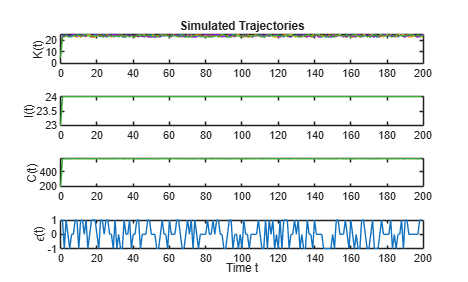

% Pick number of periods and simulations
T = 200;
sims = 5;

% Set seed for reproducibility
rng(0);

% Simulate random draws of epsilon
epsval = [-1, 0, 1];
epsprob = [0.25, 0.45, 0.30];

eps_sim = zeros(T, sims);
for s = 1:sims
    eps_sim(:, s) = randsample(epsval, T, true, epsprob);
end

% Store capital and investment in vectors
k_path = zeros(T + 1, sims);
I_path = zeros(T, sims);

k_path(1, :) = 5; % start at K0 = 5

% Simulate the optimal paths
for s = 1:sims
    for t = 1:T
        I_path(t, s) = Igrid(I_pol(k_path(t, s))); % policy returns grid index
        k_path(t + 1, s) = I_path(t, s) + eps_sim(t, s);
    end
end

% Consumption from law of motion
c_path = f_k(k_path(1:T, :)) - I_path;

% Plot optimal paths
t_k = 0:T;
t_c = 0:T-1;

figure
subplot(4,1,1); plot(t_k, k_path); ylabel('K(t)'); title('Simulated Trajectories')
subplot(4,1,2); plot(t_c, I_path); ylabel('I(t)')
subplot(4,1,3); plot(t_c, c_path); ylabel('C(t)')
subplot(4,1,4); plot(t_c, eps_sim(:, 1)); ylabel('\epsilon(t)')
xlabel('Time t')

#### f) Interpret results

Starting from $K_0 = 5$, capital jumps in a single period to about 23 and from then on the optimal investment policy is constant at $I^* = 24$ regardless of the realized capital stock. Capital therefore fluctuates within {23, 24, 25} with the variation driven by the shock rather than  by change in the family's behavior. The intuition is that the family controls only the mean of next period's capital, since $K\prime  = I + \varepsilon$, and the shock is transitory. Shocks thus do not accumulate, and there is no drift in the capital path. The level $I^* = 24$ is close to the capital stock that maximizes total available resources, $K = 24.5$, and since $\mathbb{E}(\varepsilon) = 0.05$ the family is choosing an expected capital stock of 24.05. The small gap reflects the concavity of the log payoff, the family decreases its investment a little rather than aiming exactly at the resource-maximizing point.

Consumption is smoother than capital. It starts near 197 in the first period, while capital is still being built up, and then settles between roughly 575 and 577 for the rest of the horizon. The reason the consumption window is so narrow is that total resources are nearly flat near their maximum, so the one-unit swings in capital translate into very small swings in output.

#### 4. a) Finite problem, Bellman

For $t = 0, 1, ..., T-1$:

$v_t(K_t) = \max_{I_t} \{\ln (C_t) + \beta \, \mathbb{E} (v_{t+1} (K_{t+1}) \, | \, K_t, I_t ) \}$,

where $C_t = aK_t - \frac{bK_t^2}{2} + K_t - I_t$, subject to

$K_{t+1} = I_t + \varepsilon_t$ ,

$2 \leq I_t \leq 29$, 

$aK_t - \frac{bK_t^2}{2} + K_t > I_t$ , and at $t = T$,

$v_t(K_t) = \ln (aK_t - \frac{bK_t^2}{2} + K_t)$.

#### b)

The value function is $v_t(K_t)$ which represents the present discounted value from now on of the stream of per-period payoffs when consumption is chosen optimally, given the current state of farm capital $K_t$ and the number of periods left in the family's lifetime. Unlike in the infinite horizon case it has a time subscript since the value of a given capital stock now depends on how much lifetime remains to enjoy it.

The continuation value is $\mathbb{E}(v_{t+1}(K_{t+1}))$ which represents the expected value of all future payoffs starting from the next period when consumption is chosen optimally given next period's capital stock, which is not known with certainty due to the random shock, and which involves a tradeoff with today's choice of consumption. Note that there is no continuation value at $t = T = 4$, as there is no "future" after the family's last period.

#### c)

In PS1_Q3, I solve for the value function and policy function as functions of capital stock $K$ and time $t$ for the finite horizon stochastic problem with $T = 4$ and control variable $I$. In lines 19-26, I set parameter values and the shock distribution as given in the problem. In lines 29-33, I set up the discretized $K$ and $I$ grids, where $I$ again ranges from 2 to 29 so that $K\prime  = I + \varepsilon$ stays on the grid regardless of the realized shock. In lines 39-41, I define f_k as production plus existing capital, which is the total resources available; subtracting $I$ gives consumption and taking the log gives the payoff matrix. In lines 44-45, I initialize the value and policy functions with one column for each period. In line 48, I set the value function in the last period, $t = T$, as the payoff from consuming all available resources, since there is no continuation value and therefore no reason to invest. In lines 51-62, I iterate backwards from $t = T-1$ to $t = 0$. in each period I compute, for each $I$, the expected continuation value by averaging next period's value function over the three possible realizations of $K\prime  = I + \varepsilon$ weighted by their probabilities, add this to today's payoff, and take the arg max across $I$ for each $K$, storing the results in the corresponding column of $v_t$ and $I_t$. In line 61, I convert the arg max from a grid index into the investment level it corresponds to, since the $I$ grid starts at 2 rather than 1. The result is a full time path of value and policy functions, one column for each period from $t = 0$ to $t = T$.

% Setup
clearvars;
clc;

% Define variables and parameters
rho = 0.05;
beta = 1 / (1 + rho);
a = 48.05;
b = 2;

% Define shock distribution
epsval = [-1, 0, 1];
epsprob = [0.25, 0.45, 0.30];

% Create I grid
Igrid = 2:29;

% Create k
num_k = 30;
k = (1:num_k)';

% Number of periods
T = 4;

% Describe laws of problem
f_k = a*k - b*k.^2 / 2 + k;
c = f_k - Igrid; % consumption for every pair
pii = log(c); % payoffs

% Initialize value and policy functions
v_t = zeros(num_k, T + 1);
I_t = zeros(num_k, T);

% Value function at t = T: consume all available resources
v_t(:, T+1) = log(f_k);

% Solve using backwards iteration
for t = T-1:-1:0
    % Expected continuation value for each I
    v_next = v_t(:, t+2);
    Ev = epsprob(1)*v_next(Igrid-1) + epsprob(2)*v_next(Igrid) ...
        + epsprob(3)*v_next(Igrid+1);
    vv = pii + beta * Ev';

    % For each k, choose I to maximize vv
    [v_now, I_now] = max(vv, [], 2);
    v_t(:, t+1) = v_now;
    I_t(:, t+1) = reshape(Igrid(I_now), [], 1); % convert index to level
end

% Print results in table
results4 = array2table([k, v_t, I_t], 'VariableNames', ...
    {'K','v_t0','v_t1','v_t2','v_t3','v_t4','I_t0','I_t1','I_t2','I_t3'})

results4 = 30×10 table
    K      v_t0      v_t1      v_t2      v_t3      v_t4     I_t0    I_t1    I_t2    I_t3
    __    ______    ______    ______    ______    ______    ____    ____    ____    ____

     1    25.917    20.689    15.199    9.4396    3.8722     16      16      16      16 
     2    26.848     21.62     16.13    10.367    4.5444     20      20      20      20 
     3    27.321    22.093    16.603    10.839    4.9283     22      22      22      22 
     4    27.631    22.402    16.912    11.148    5.1941     23      23      23      22 
     5    27.858    22.629    17.139    11.375    5.3948     23      23      23      23 
     6    28.

#### d)

Next I simulate and plot the optimal trajectories of the shock, capital $K(t)$, investment $I(t)$, and consumption $C(t)$ for the finite horizon problem. In lines 74-78, I draw the shock realizations: for each of the five simulations I take five independent draws from the given distribution of $\varepsilon$. Note that only the first four draws affect the solution, since the draw at $t = T$ would determine a capital stock at $T+1$ which is after the family's lifetime. In lines 81-85, I initialize the capital, investment, and consumption paths and set initial capital to $K_0 = 5$ for every simulation. In lines 88-93, I fill in the paths for each simulation and each decision period $t = 0$ to $T-1$, investment is the time-specific policy function evaluated at the current capital stock and the current period, and next period's capital is that investment plus the shock following the law of motion $K' = I + \varepsilon$. In lines 96-97, I compute consumption, as in c) above, except at $t = T$ where the family invests nothing and consumes all available resources.. In lines 100-108, I plot the shock, capital, investment, and consumption against time in four stacked plots with one line per simulated trajectory. Note that the investment trajectories coincide exactly across all five simulations, so only one curve is visible in that panel.

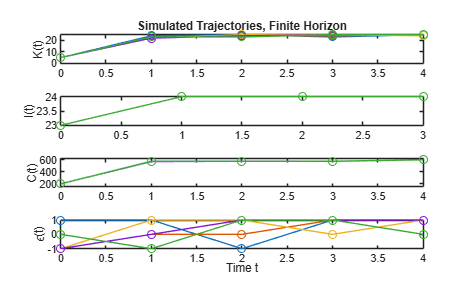

% Set seed for reproducbility
rng(0);

% Simulate random draws of epsilon
sims = 5;
eps_sim = zeros(T + 1, sims);
for s = 1:sims
    eps_sim(:, s) = randsample(epsval, T + 1, true, epsprob);
end

% Store capital, investment, and consumption in vectors
k_path = zeros(T + 1, sims);
I_path = zeros(T, sims);
c_path = zeros(T + 1, sims);

k_path(1, :) = 5; % start at K0 = 5

% Simulate the optimal paths
for s = 1:sims
    for t = 0:T-1
        I_path(t+1, s) = I_t(k_path(t+1, s), t+1);
        k_path(t+2, s) = I_path(t+1, s) + eps_sim(t+1, s);
    end
end

% Consumption from law of motion, all resources consumed at t = T
c_path(1:T, :) = f_k(k_path(1:T, :)) - I_path;
c_path(T+1, :) = reshape(f_k(k_path(T+1, :)), 1, []);

% Plot optimal paths
t_all = 0:T;
t_dec = 0:T-1;

figure
subplot(4,1,1); plot(t_all, k_path, '-o'); ylabel('K(t)'); title('Simulated Trajectories, Finite Horizon')
subplot(4,1,2); plot(t_dec, I_path, '-o'); ylabel('I(t)')
subplot(4,1,3); plot(t_all, c_path, '-o'); ylabel('C(t)'); ylim([150 620])
subplot(4,1,4); plot(t_all, eps_sim, '-o'); ylabel('\epsilon(t)')
xlabel('Time t')

#### e)

The optimal policy in the finite horizon problem is almost exactly the policy from the infinite horizon problem: starting from $K_0 = 5$ the family invests 23, and from $K = 9$ upward it invests 24 in every decision period from $t = 0$ through $t = 3$. At $K = 4$ in the final decision period, optimal investment falls to 22 rather than 23. Capital therefore jumps once from 5 into the low 20s and then fluctuates in {23, 24, 25} for the rest of the family's lifetime with the variation driven entirely by the realized shocks. As in the infinite horizon case, the shocks are not cumulative since the family resets investment to 24 in the following period regardless of the draw it received. This is why the five simulated investment trajectories are identical despite the random different shock paths.

Consumption begins near 197 while capital is still being built up, settles around 565 and 577 in the middle periods, and jumps to about 600 at $t = T$. This is a jump of approximately 24 units or exactly the investment the family no longer makes once there is no future to invest for. This is the same pattern as in the deterministic finite horizon case. The value function is of course much lower than in the infinite horizon problem, about 27.9 compared to 132.4 at $K_0 = 5$, simply because only five periods of payoffs are being summed.

### **III. Investment Under Uncertainty**

#### **5. a) Orthodox theory**

The orthodox theory of investment is to invest when the net present value (NPV) of the project is positive, i.e. the present discounted value (PDV) of the entire stream of payoffs of the project are greater than (or equal to) zero. The assumption implicit here is that either (1) the investment is reversible, or (2) the investment is irreversible, but is a now-or-never opportunity.

#### b) Characteristics unaccounted for

The orthodox theory fails to account for the following typical characteristics of investment projects:

- Most often, investments are at least partially irreversible; going back requires significant funds/time/energy.

- In the real world an agent can typically delay the investment decision until the next period to gain more information.

- There is often uncertainty about the future payoffs of the investment.

#### c) Real options approach

In the real options approach to investment decision-making, a firm with an opportunity to invest has the right but not the obligation to buy an asset at some future time of its choosing. When a firm makes an irreversible investment, it exercises its option to invest, but the lost option value is an opportunity cost that must be factored into the investment decision.

#### 6. a) Search and stopping

In the job search problem, in each period the searcher 'draws' a wage offer, and decides whether to accept ('stops' the search) or reject and continue the search. The optimal solution is a reservation wage rule: accept an offer if and only if the wage drawn is at least $w^*$*, *and otherwise reject and draw again next period.  This differs from the orthodox theory, which would have the worker accept any offer whose PDV exceeds the outside option, because orthodox theory treats the decision as now-or-never. Here accepting is irreversible but also delay-able so waiting has value and the optimal cutoff is strictly higher. Intuition: taking the job today forgoes the chance of a better draw tomorrow. A more patient worker (with higher $\beta$) finds waiting more worthwhile.

#### b) Cutoff wage

The cutoff represents the expected value of continuing the search in future periods,  The cutoff is defined by the indifference condition $w^* = \beta \, \mathbb{E} (v(w'))$. This is opportunity cost of accepting a job, or the option value the worker gives up by exercising it. A worthwhile offer must compensate the worker not only for the reservation wage of another period (potentially just the value of being unemployed, such as unemployment benefits), but also permanently losing the option to keep sampling the wage distribution. At $w = w^*$ the worker is exactly indifferent. This is the same object as the investment trigger discussed above.

#### 7. Environmental policy

There are two sources of irreversibility to consider when developing and adopting environmental policy, each with their own implications for adoption timing:

- Environmental policies may cause firms or society to make irreversible investments in order to comply. This suggests that policy adoption should wait to gain more information and ensure these are worthwhile investments.

- Environmental damage may be partially or entirely irreversible. This suggests that policy should be adopted as soon as possible to avert these damages.

Thus, the two sources of irreversibility represent a trade-off to be made when deciding on optimal timing for environmental policy.

#### 8. Example of investment under uncertainty in the power generation sector

#### a) Problem overview

The problem I have chosen is the decision facing the owner of an existing coal-fired electricity generating unit: whether, and when, to incur the sunk cost of converting ("repowering") that unit to burn natural gas, as against continuing to operate it on coal. I have chosen this problem for three reasons. First, it is the empirical setting of my ongoing research, so I already have knowledge of the relevant literature. Second, it is an unusually clean instance of the canonical investment problem: the conversion cost is large and almost entirely unrecoverable, the decision is repeatedly deferrable rather than now-or-never, and the payoff depends on a price spread that is observably volatile. Third, the aggregate stakes are large, since these units are a substantial share of U.S. power-sector emissions.

#### b) Background

The U.S. coal fleet consists of unusually long-lived capital. Most units were built decades ago and many were grandfathered under vintage-differentiated environmental regulation, which imposes stricter standards on new sources than on existing ones and so extends the economic life of older units beyond what a level playing field would support (Stavins 2005; Bialek, Gregory, and Revesz 2025). The economics of operating that capital have deteriorated sharply as abundant shale gas and falling renewable costs have compressed coal-fired operating margins and pushed a large share of the fleet toward the margin of profitability (Davis, Holladay, and Sims 2021).

This makes the fate of each remaining unit an important economic and policy question. Repowering to natural gas is a 'middle path' between continuing to burn coal and abandoning the asset outright: repowering retains the site and the grid interconnection while cutting emissions per MWh. How quickly firms take that path determines both the emissions trajectory of the power sector and the scale of asset value destroyed in this energy transition. This consideration bridges this problem from environmental literature into work on stranded assets and financial stability (Rozenberg et al. 2020; Daumas 2024).

The problem is also interesting because, as I have found in my research, firms visibly delay from the positive-NPV rule. Units continue burning coal for years at fuel prices that a static calculation says should already have triggered conversion. Under the orthodox theory this looks like managerial error. Under the real options approach it can be exactly optimal, and the distinction matters for policy: if delay reflects option value rather than inattention, then subsidies and carbon prices act on a threshold that is higher than the naive break-even point, and the uncertainty surrounding a policy can delay the transition even as the policy's expected impact accelerates it (Chronopoulos, Hagspiel, and Fleten 2016; Gowrisankaran, Langer, and Zarek 2024).

#### c) Agent

The decision-maker is the firm that owns and operates the generating unit—an investor-owned utility, a publicly owned power authority, or a merchant generator, with the decision typically made at the level of the ultimate parent firm. In each period, that firm observes the current state of the world and chooses between (i) continuing to burn coal for another period, or (ii) paying a one-time, sunk conversion cost to repower the unit to natural gas, after which it earns the gas-fired operating margin for the remainder of the unit's life. (Note that the firm could also choose to retire/scrap the unit outright, but I abstract from this option in this analysis).

Thus the firm's real choice is not whether the gas configuration is more profitable than the coal configuration, but when, if ever, to commit to it. Because option (ii) is available next period as well as this one, and because the conversion cannot be undone once made, the firm is choosing the timing of an irreversible commitment rather than selecting between two static alternatives.

#### d) Uncertainty

The repowering decision exhibits all three defining characteristics of an investment decision under uncertainty:

- Irreversibility: The conversion expenditure is largely sunk. It is comprised of boiler modification or replacement, burner and fuel-handling conversion, and construction of additional pipelines to connect the site to a gas main. These costs are specific to that unit at that site. The coal-side assets retired in the process (coal yard, pulverizers, ash handling) cannot be costlessly reinstated. A firm that converts and then sees gas prices rise relative to coal cannot recover its investment costs by converting back (Dixit and Pindyck 1994).

- Uncertainty: The payoff to converting is the present value of the gas-fired operating margin minus the coal-fired margin the unit would otherwise have earned. That differential depends mainly on delivered gas and coal prices and potential costs from compliance with future environmental regulation (which is often harsher for dirtier coal), which are volatile over the multi-decade horizon of the plant's future lifetime. Uncertainty about future environmental regulation, which shifts the coal-fired margin directly and whose resolution is itself stochastic, is crucial here (Gowrisankaran, Langer, and Zarek 2024).

- Leeway over timing: The opportunity to repower is not now-or-never. So long as the unit remains operable, the firm may convert this year, next year, or in ten years, and by waiting it observes another realization of fuel prices and another period of regulatory developments before committing. (Note though that for old units, conversion could potentially become more expensive upon waiting at the infrastructure of the plant itself degrades with age!)

Thus because the investment is irreversible and deferrable, both of the implicit assumptions underpinning the orthodox NPV rule fail, and the problem becomes one of optimal stopping: the firm must choose not merely whether conversion is worthwhile, but when to exercise an option it holds and cannot repurchase once spent (Dixit 1989, as in class notes).

#### e) Bellman equation

Let time be discrete, indexed by $t$, with discount factor $\beta \in (0,1)$. Let the indicator $I_t \in \{0,1\}$ equal 1 if the firm converts the unit to gas in period t and 0 otherwise. Conversion is absorbing, once $I_t = 1$ the option is spent and the decision problem ends. The state is $s_t = (P_t , z_t)$ where $P_t$ is the per-period gain in operating margin from running the unit gas-fired rather than coal-fired, driven by delivered gas and coal prices, the unit's heat rates, and the wholesale power price. The regulatory state $z_t$ is a Markov chain over environmental compliance regimes, which shifts $P_t$ (a stricter regime raises the cost of burning coal, and so raises the gain from converting) and governs the transitions the firm anticipates. Both components evolve as a Markov process, so $\mathbb{E}(\cdot | s_T)$ summarizes the firm's beliefs about the future. Let K denote the sunk conversion cost, so the payoff to converting in state $s_t$ is the discounted stream of margin gains minus that cost:

$\pi(s_t) = \mathbb{E} [ \sum_{j \geq 0} \beta^j P_{t+j} \, | \, s_t) - K]$ . For $v(s_t)$ the value of holding the unconverted unit in state $s_t$, in each period the firm chooses $I_t$ to solve

 $v(s_t) = \max_{I_t \in \{0,1\}} \{{ I_t \pi(s_t) + (1-I_t) \cdot \beta \, \mathbb{E}(v(s_{t+1}\, | \,s_t, I_t = 0) \}$.

Thus the firm converts in period $t$ when $\pi(s_t) \geq \beta \, \mathbb{E}(v(s_{t+1}) \, | \, s_t, I_t = 0)$ and otherwise continues to burn coal for another period. Here $\pi(s_t)$ is the NPV of repowering and the discounted continuation value is the expected value of keeping the conversion option alive for another period.

#### f) Optimal solution

Since $\pi$ is increasing in the fuel margin differential $P$, and the problem is stationary conditional on the regulatory state, the optimal policy is a trigger rule. For each regulatory state $z$ there is a threshold $P^*(z)$ such that the firm does the conversion when $P_t \geq P^*(z_t)$. At this threshold the firm is indifferent between repowering and waiting (burning coal for another period). Thus $P^*(z)$ is defined by $\pi (P^*(z), z) = \beta \, \mathbb{E}(v(s_{t+1}\, | \,s_t, I_t = 0)$.

This is in contrast to the orthodox theory, which would suggest investment when NPV is positive, i.e. when $\pi > 0$. The optimal rule from real options theory has a strictly higher threshold, meaning there is a region where NPV is positive but the firm still optimally burns coal, because the continuation value is strictly positive whenever the future is uncertain.

The intuition is that exercising the option to repower removes it. When the firm converts it both pays the conversion cost $K$ and also gives up the option to convert later under better information. This forgone continuation value is an opportunity cost that must be factored into the decision alongside K. The orthodox rule does not consider this and so suggests investment too early. This option value is a result of a certain asymmetry created by irreversibility---a firm that waits and sees the spread widen can still convert later in a better state, whereas a firm that converts is stuck with a gas-fired unit even if the later state shows a negative value of burning gas instead of coal. One implication of this asymmetry is that the gap between the two thresholds widens with the volatility of the fuel margin differential, since greater dispersion raises the value of the option without changing the expected NPV. Uncertainty therefore delays conversion as well.